 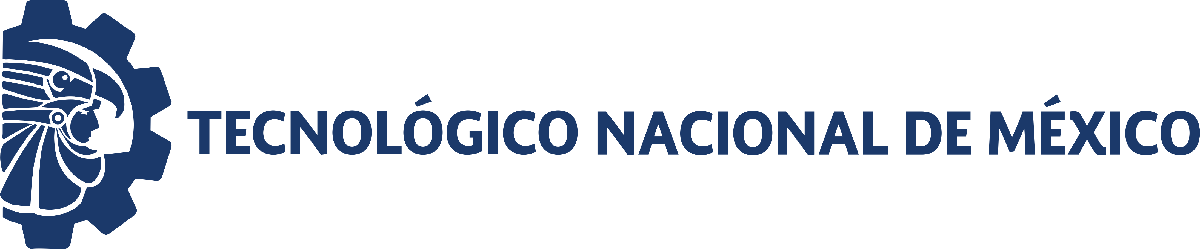                                 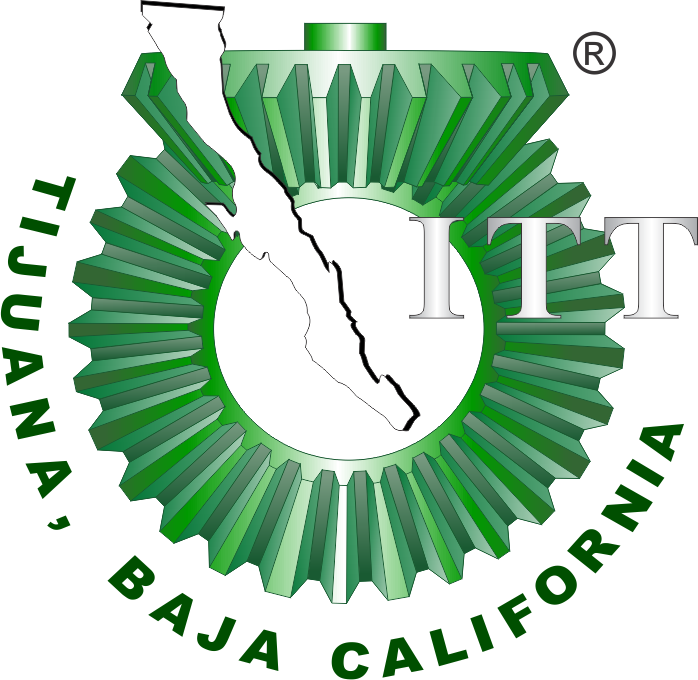

# Proyecto Final: Sistema endocrino,Hashimoto(Tiroiditis cronica)

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

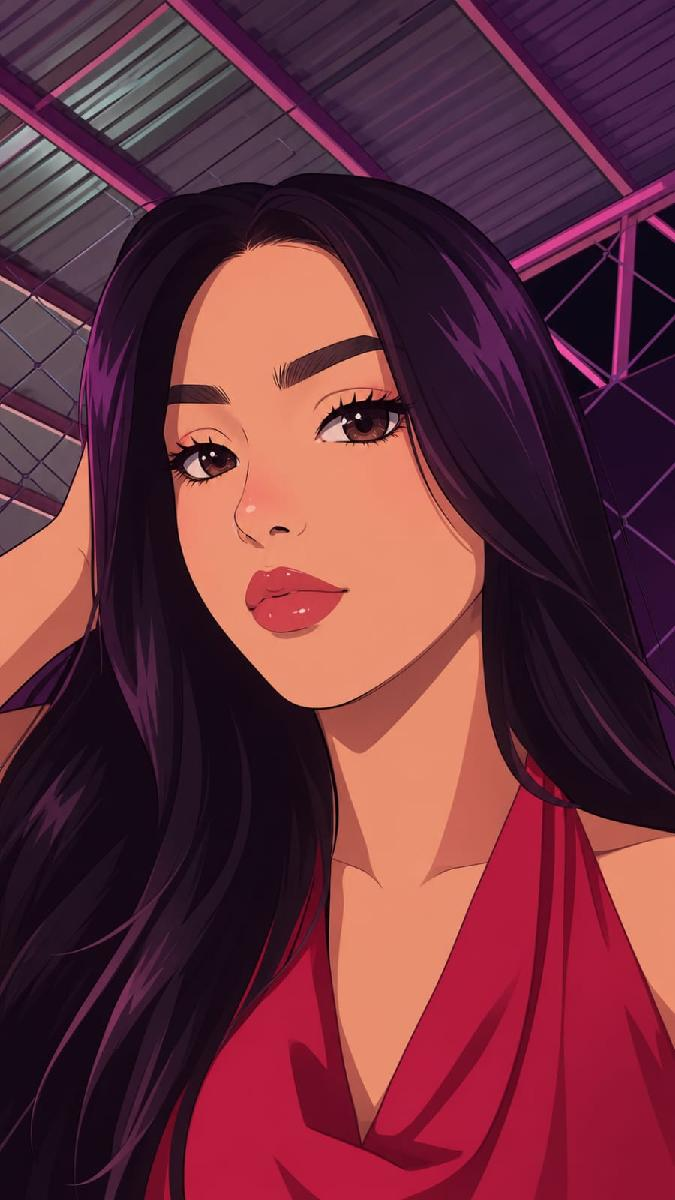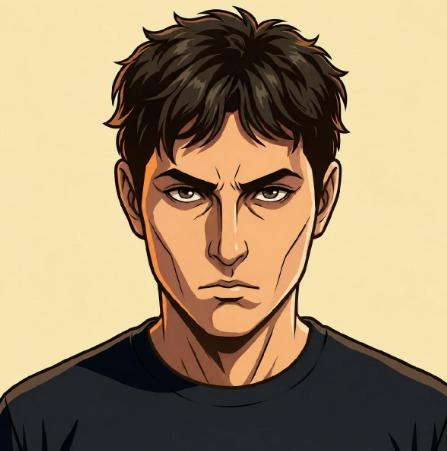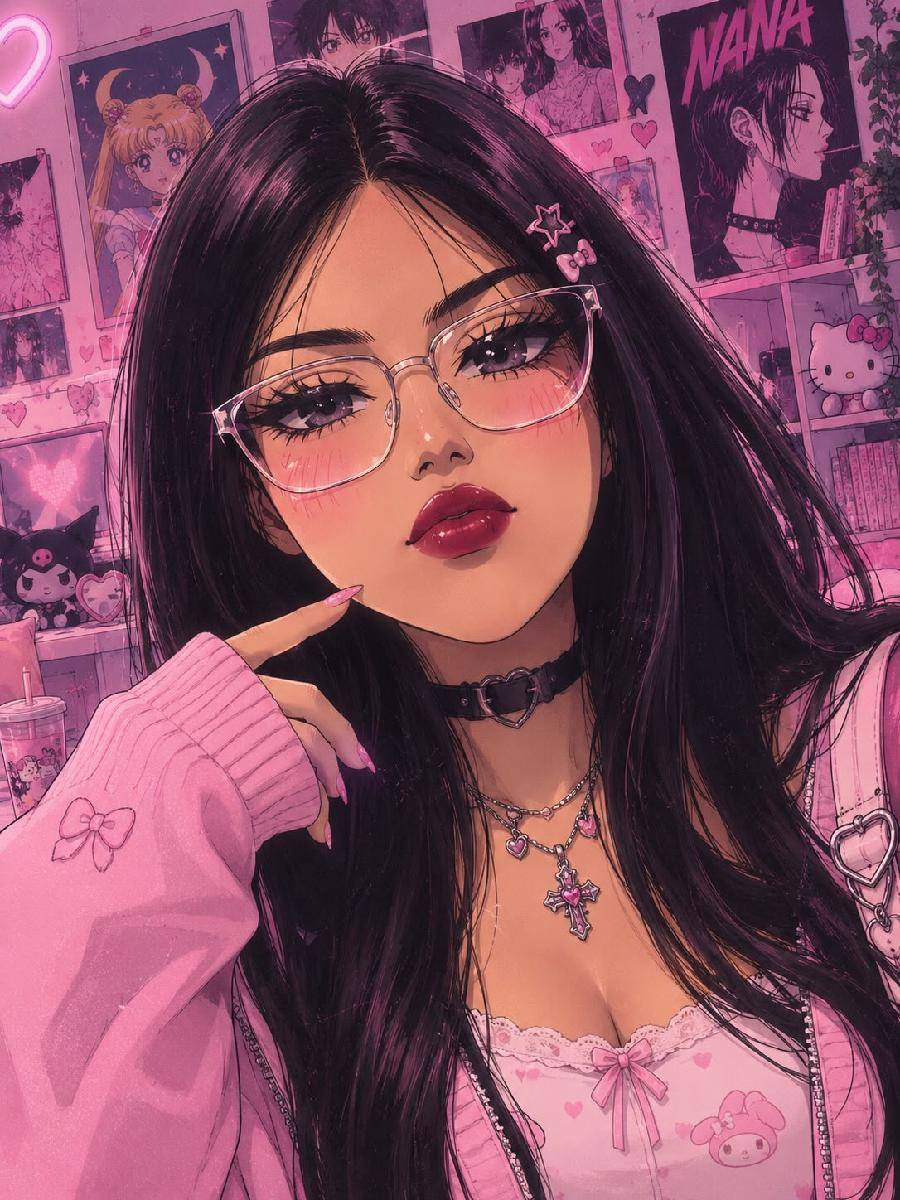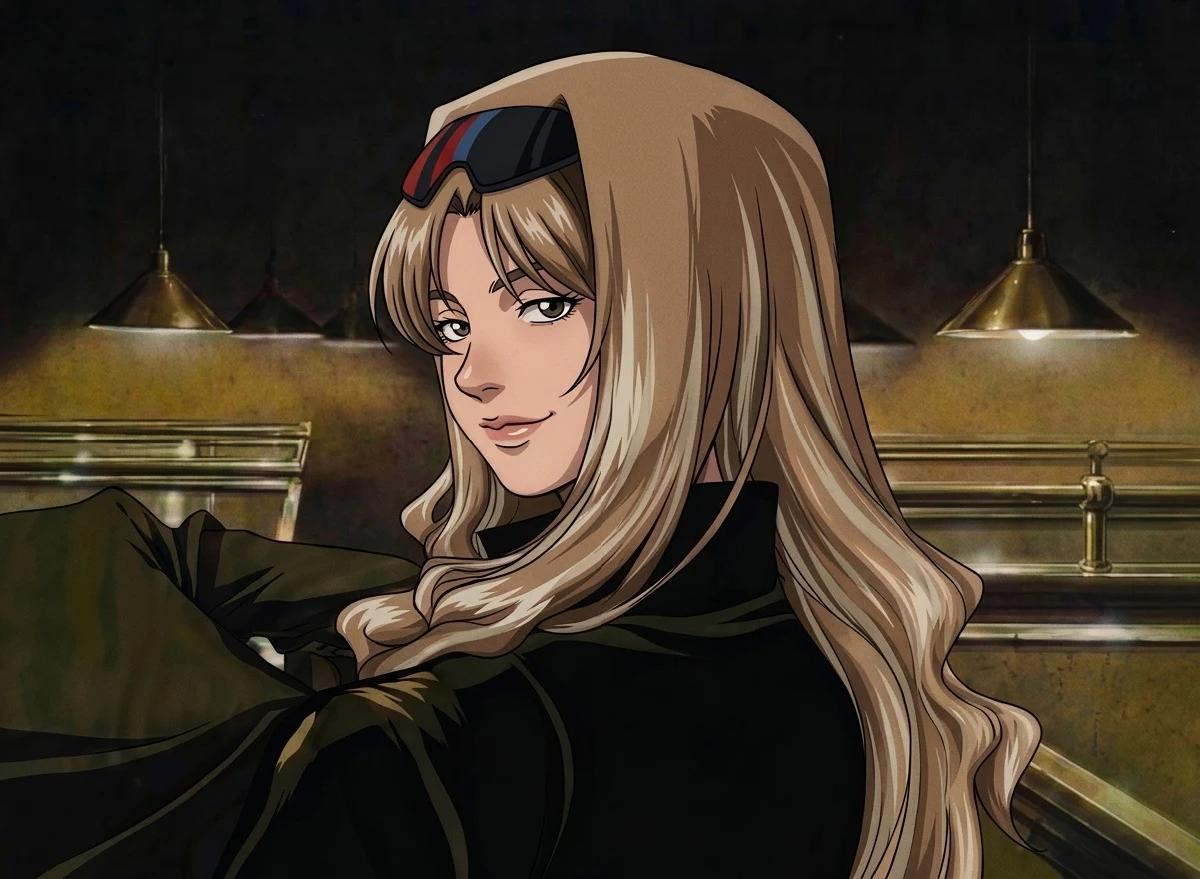

Integrantes y numero de control:

**Castañeda Nieblas Lorena Lizel - L23210695**

**Preciado Amezquit Carlos Samuel -  C19211840**

**Rincon Jimenez Tessa - L22210795**

**Vazquez Alvear Nicole - C20210923**

Correos institucionales: 

**L23210695@tectijuana.edu.mx**

**LC19211840@tectijuana.edu.mx**

**L22210795@tectijuana.edu.mx**

**LC20210923@tectijuana.edu.mxs**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

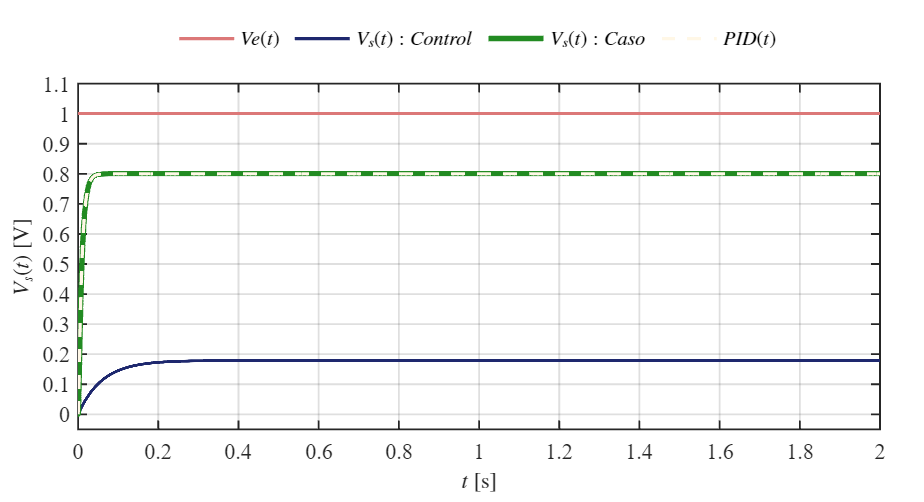

clc; clear; close all; warning('off','all')

tend = '2';
file = 'Hashimoto';

open_system(file);

parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-4';

%% Simulación
x = sim(file, parameters);

%% Respuesta a la simulación
plotsignals(x.tout, x.Ve, x.Vs_PID, x.Fsy, x.Vs_ctrl, 'Hashimoto_')

## **Modelo de EDOs**

function Vs = endocrino(par, Ve, t)
    R1  = par(1);
    L   = par(2);
    Ceq = par(3); % C1 + C2
    R2  = par(4);
    R3  = par(5);

    if isscalar(Ve)
        Ve = ones(size(t)) * Ve;
    end

    dt = t(2) - t(1);
    n = length(t) - 1;

    Vc = zeros(length(t), 1);
    Fe = zeros(length(t), 1);
    Vs = zeros(length(t), 1);

    for i = 1:n
        dFe = (Ve(i) - R1*Fe(i) - Vc(i)) / L;
        Fe(i+1) = Fe(i) + dFe * dt;
        
        dVc = (Fe(i+1) - Vc(i)/(R2 + R3)) / Ceq;
        Vc(i+1) = Vc(i) + dVc * dt;
        
        Vs(i+1) = Vc(i+1) * (R3 / (R2 + R3));
    end
end

## **Respuesta a la simulacion**

   
function plotsignals(t, Ve, Vs_PID , Fsy, Vs_ctrl, signal)

    t       = t(:);
    Ve      = Ve(:);
    Vs_ctrl = Vs_ctrl(:);
    Fsy     = Fsy(:);
    Vs_PID  = Vs_PID(:);

    fig = figure('Color', 'w', 'Units', 'inches', 'Position', [1, 1, 7, 3.8]);

    tiledlayout(1, 1, 'Padding', 'compact', 'TileSpacing', 'compact');
    ax = nexttile;

    hold(ax, 'on');
    grid(ax, 'on'); 
    box(ax, 'on');

    set(ax, 'FontName', 'Times New Roman', 'FontSize', 12, 'LineWidth', 1);

    clr1 = [220, 120, 120]/255;
    clr2 = [255, 247, 230]/255;
    clr3 = [30, 40, 110]/255;
    clr4 = [34, 139, 34]/255;

  plot(ax, t, Ve, '-', 'LineWidth', 1.8, 'Color', clr1)
    plot(ax, t, Fsy, '-', 'LineWidth', 1.8, 'Color', clr3)
    plot(ax, t, Vs_PID, '-', 'LineWidth', 3.0, 'Color', clr4)
    plot(ax, t, Vs_ctrl, '--', 'LineWidth', 1.8, 'Color', clr2) 

    L = legend(ax, '$Ve(t)$', '$V_s(t):Caso$', '$PID(t)$', '$V_s(t):Control$');

    L = legend(ax, '$Ve(t)$','$V_s(t):Control$','$V_s(t):Caso$','$PID(t)$');

    set(L, 'Interpreter', 'latex','Location', 'northoutside','Orientation', 'horizontal','Box', 'off','FontSize', 11)

   
    xlabel(ax, '$t$ [s]', 'Interpreter', 'latex', 'FontSize', 12)
    ylabel(ax, '$V_s(t)$ [V]', 'Interpreter', 'latex', 'FontSize', 12)

    xlim(ax, [0 2]);
    xticks(ax, 0:0.2:2);

    ylim(ax, [-0.05 1.1]);
    yticks(ax, 0:0.1:1.1);
    exportgraphics(fig, [signal, 'matlab.pdf'], 'ContentType', 'vector')

end